## **1D Kalman Filter**

%problem attached: https://cecas.clemson.edu/~ahoover/ece854/labs/lab4-KF.pdf


clc;
clear;
%getting the measurement data
urlwrite("https://cecas.clemson.edu/ahoover/ece854/labs/1D-data.txt","measurement_Q1")

ans = 'C:\Users\shubh\OneDrive - Clemson University\CUICAR\fall_2022\ece8540\assignments\lab4\measurement_Q1'

inp_filename = "measurement_Q1.txt"

inp_filename = "measurement_Q1.txt"

fid = fopen(inp_filename); % open the file
iCtr = 0;
y_q1=[];
while ~feof(fid) % loop over the following until the end of the file is reached.
  line = fgets(fid); % read in one line
  y_q1(end+1) = str2double(line);
end

y_q1=y_q1';


%assuming a time array corresponding with measurement data with a frequency of 1Hz
time_q1=(1:0.5:length(y_q1)/2);


%assuming a position array corresponding with a predicted state in column 1
%and an updated state in column 2
x_q1=zeros(length(y_q1),2);

x_q1(1,1:end) = y_q1(1)*0.9;


%assuming a velocity array corresponding with each position state for a
%constant velocity model
x_dot_q1 = zeros(length(y_q1),2);

x_dot_q1(1,1:end) = y_q1(2)-y_q1(1);

%we know that there's measurement noises and dynamic noises
S_prev_q1 = [0.02, 0.1; 0.04, 0.25];
S_next_q1 = 0;
R_q1 = 0.01;
M_q1 = [1, 0];
var_x_dot = 0.3;
Q_q1 = [0, 0; 0, var_x_dot^2];

%Kalman_filter(x_q1,x_dot_q1,y_q1,time_q1,S_prev_q1,S_next_q1,R_q1,M_q1,Q_q1,2)

%creating the loop for running the filter
for i=2:1:length(y_q1)-1
    %step 1: Predict next state
    phi_q1 = [1, time_q1(i)-time_q1(i-1); 0, 1];
    X_pred_q1 = phi_q1*([x_q1(i-1,2),x_dot_q1(i-1,2)]');
    %placing predictions in the state variable array
    x_q1(i,1)=X_pred_q1(1);
    x_dot_q1(i,1)=X_pred_q1(2);
    
    %step 2: predict next state covariance
    S_next_q1 = phi_q1*S_prev_q1*(phi_q1') + Q_q1;

    %step 3: obtain measurements (there as input)
    Y_q1 = [y_q1(i);0];

    %step 4: calculate Kalman Gain
    K_q1 = S_next_q1*(M_q1)'*((M_q1*S_next_q1*(M_q1)'+ R_q1)^-1);

    %step 5: update state
    X_upd_q1 = X_pred_q1 + K_q1*(y_q1(i)-(M_q1*X_pred_q1));
    %placing predictions in the state variable array
    x_q1(i,2)=X_upd_q1(1);
    x_dot_q1(i,2)=X_upd_q1(2);

    %step 6: update state covariance
    S_prev_q1 = [eye(2,2) - K_q1*M_q1]*S_next_q1;
end
display("done");

    "done"



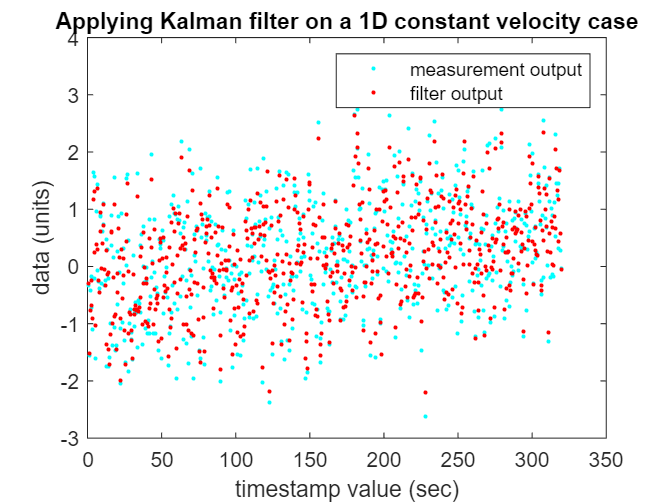


figure()
plot(time_q1',y_q1(1:end-1),'.c')
ylabel('data (units)');
xlabel('timestamp value (sec)');
hold on;
plot(time_q1',x_q1(1:end-1,2),'.r');
title('Applying Kalman filter on a 1D constant velocity case');
legend('measurement output','filter output','location','northeast');

    "done"



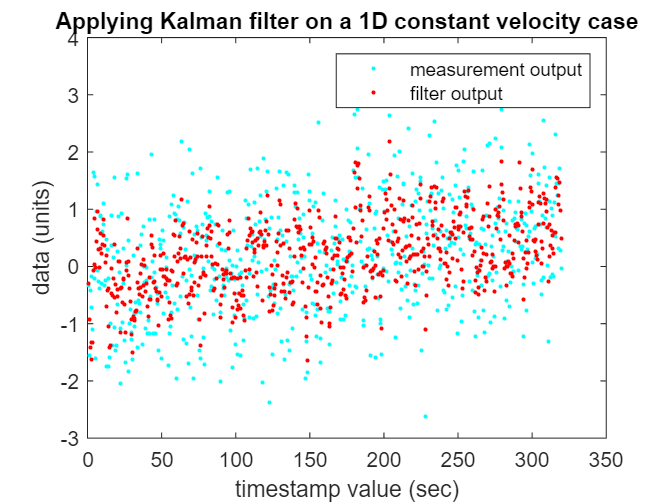

%for a different ratio, making measurement noise more
x2_q1=zeros(length(y_q1),2);
x2_q1(1,1:end) = y_q1(1)*0.9;

x2_dot_q1 = zeros(length(y_q1),2);
x2_dot_q1(1,1:end) = y_q1(2)-y_q1(1);

var_x_dot = 0.3;
S_prev_q1 = [0, 0; 0, var_x_dot^2];
S_next_q1 = 0;
R2_q1 = 0.75;
M2_q1 = [1, 0];
Q2_q1 = [0, 0; 0, (var_x_dot^2)];

Kalman_filter(x2_q1,x2_dot_q1,y_q1,time_q1,S_prev_q1,S_next_q1,R2_q1,M2_q1,Q2_q1,2)

It can be observed that as the measurement noise increases, the filter assumes less confidence in sensor readings and gives more weightage to the predictions. Hence, it can be seen that the filter outputs are concentrated in an area while the measurement data is distinct at most of the places.

    "done"



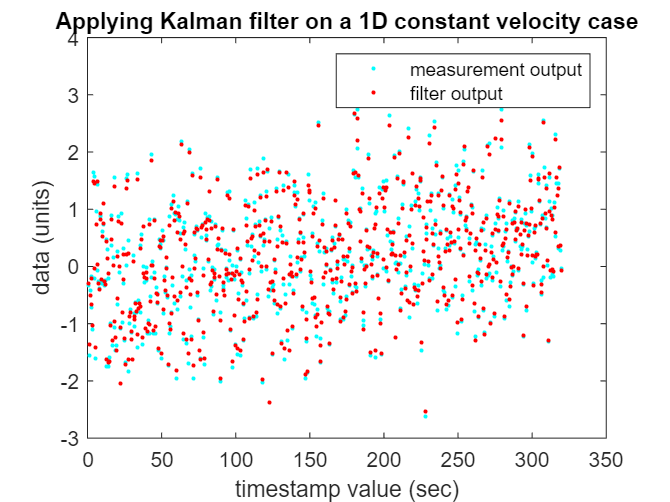

%for a different ratio, making dynamic noise more
x3_q1=zeros(length(y_q1),2);
x3_q1(1,1:end) = y_q1(1)*0.9;

x3_dot_q1 = zeros(length(y_q1),2);
x3_dot_q1(1,1:end) = y_q1(2)-y_q1(1);

var_x_dot = 0.3;
S_prev_q1 = [0, 0; 0, var_x_dot^2];
S_next_q1 = 0;
R3_q1 = 0.01;
M3_q1 = [1, 0];
Q3_q1 = [0, 0; 0, (var_x_dot^2)*7.5];

Kalman_filter(x3_q1,x3_dot_q1,y_q1,time_q1,S_prev_q1,S_next_q1,R3_q1,M3_q1,Q3_q1,3)

It can be observed that as the dyanmic noise increases, the filter assumes more confidence in sensor readings and gives less weightage to the predictions. Hence, it can be seen that the filter outputs are generated very similar to the measurement data which indicates a divergence from the predicted values.

function Kalman_filter(x2_q1,x2_dot_q1,y_q1,time_q1,S_prev_q1,S_next_q1,R_q1,M_q1,Q_q1,fignum)
    for i=2:1:length(y_q1)-1
        %step 1: Predict next state
        phi_q1 = [1, time_q1(i)-time_q1(i-1); 0, 1];
        X_pred_q1 = phi_q1*([x2_q1(i-1,2),x2_dot_q1(i-1,2)]');
        %placing predictions in the state variable array
        x2_q1(i,1)=X_pred_q1(1);
        x2_dot_q1(i,1)=X_pred_q1(2);
        
        %step 2: predict next state covariance
        S_next_q1 = phi_q1*S_prev_q1*(phi_q1') + Q_q1;
    
        %step 3: obtain measurements (there as input)
        Y_q1 = [y_q1(i);0];
    
        %step 4: calculate Kalman Gain
        K_q1 = S_next_q1*(M_q1)'*((M_q1*S_next_q1*(M_q1)'+ R_q1)^-1);
    
        %step 5: update state
        X_upd_q1 = X_pred_q1 + K_q1*(y_q1(i)-(M_q1*X_pred_q1));
        %placing predictions in the state variable array
        x2_q1(i,2)=X_upd_q1(1);
        x2_dot_q1(i,2)=X_upd_q1(2);
    
        %step 6: update state covariance
        S_prev_q1 = [eye(2,2) - K_q1*M_q1]*S_next_q1;
    end
    display("done");


    figure(fignum)
    plot(time_q1',y_q1(1:end-1),'.c')
    ylabel('data (units)');
    xlabel('timestamp value (sec)');
    hold on;
    plot(time_q1',x2_q1(1:end-1,2),'.r');
    title('Applying Kalman filter on a 1D constant velocity case');
    legend('measurement output','filter output','location','northeast');
end